%%%% HW 1

## Problem 12c - w/ new Type III BC + Iterative Solving

Engs105, W24 - Prof. Paulsen

### Numerical Solution

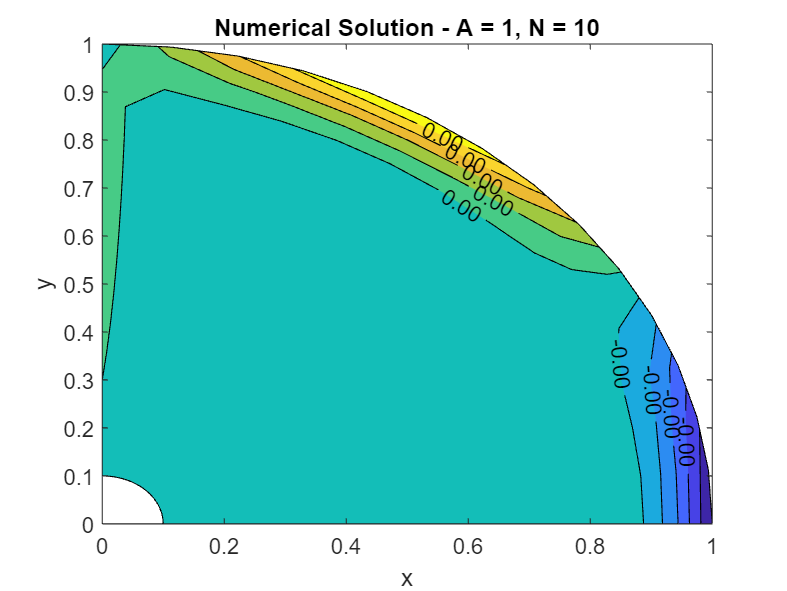

clear; close all
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A = 1
N = 15;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("jacobi.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - A = 1, N = 10')
xlabel('x')
ylabel('y')